## **PL 2 Probabilidade, Probabilidade Condicional e Independência**

### **2.1. Probabilidade**

**4. Festa com n pessoas.**

a) Qual o menor valor **n **para que a probabilidade de duas ou mais pessoas terem a mesma data de aniversário (dia e mês) seja superior a 0,5 (365 dias num ano)?

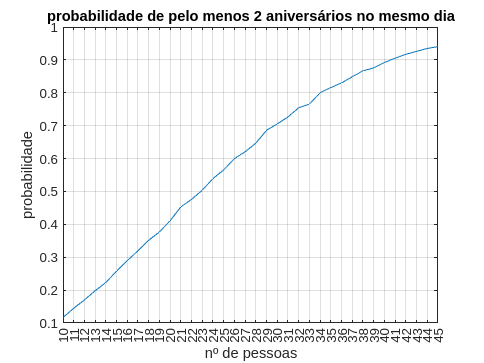

numExp = 1e4;
% comecei entre 10 e 150 -> deu por volta dos 25 entao reduzi para ver
% melhor a escala
% poderia ter sido feito com um while loop para parar a simulação quando o
% valor pretendido fosse obtido, teria sido mais eficaz
nPessoas = 10:1:45;
dias = 365;
matrizProbColisaoAniv = zeros(1,length(nPessoas));

for n = 1:length(nPessoas)
    casosFav_a = 0;
    for i = 1:numExp
        matrizAniv = randi(365,1,nPessoas(n));
        if length(matrizAniv) > length(unique(matrizAniv))
            casosFav_a = casosFav_a + 1;
        end
    end
    matrizProbColisaoAniv(n) = casosFav_a/numExp;
end

% gráfico
plot(nPessoas,matrizProbColisaoAniv)
title('probabilidade de pelo menos 2 aniversários no mesmo dia');
xlabel('nº de pessoas');
xticks(10:1:45);
ylabel('probabilidade');
grid on;

%

**R: **Pela observação do gráfico, o valor n mais pequeno para que a probabilidade de haver pelo menos 2 pessoas com o mesmo aniversário seja superior a 0,5 é 23.

b) Menor valor de **n** para que a probabilidade anterior seja superior a 0,9?

**R: **Observando o gráfico anterior, e correndo algumas simulações, o valor n para que a probabilidade haver colisão de pelo menos um aniversário seja superior a 0,9  é 41.